% Part B
clear;clc;

f = [-50000 -100000]; % cost per unit of output

A = [7 2; % commercial seen by women constraint
     2 12; % commercial seen by men constraint
     -1 0; % sign constraint for comedy commercials
     0 -1]; % sign constraint for football comercials 

b = [28; 24; 0; 0]; 

[x, fval, exitflag, output, lambda] = linprog(f, A, b);

Optimal solution found.




fprintf('To minimize cost,  Dorian Auto purchases %2.0f comedy and %2.0f football commercials for the campaign\n',ceil(x)) % prints number of comedy and football commercials rounded to next smallest integer not smaller than x

To minimize cost,  Dorian Auto purchases  4 comedy and  2 football commercials for the campaign


% Part C
clear;clc;

W = 20:40; % Population range of high-income women viewers
z = zeros (5,numel(W)); % Create a zero matrix for storing results

f = [-50000 -100000]; % cost per unit of output

A = [7 2; % commercial seen by women constraint
     2 12; % commercial seen by men constraint
     -1 0; % sign constraint for comedy commercials
     0 -1]; % sign constraint for football comercials 

for k = 1:numel(W)
    W1 = W(k);   % number of women viewers
    b = [W1; 24; 0; 0]; 
    [x, fval, exitflag, output, lambda] = linprog(f,A,b);
    
    z ([1 2], k) = x; % Stores comedy commericals in row 1, football commercials in row 2 
    z (3, k) = -fval; % Stores total continuous cost in row 3
    z (4, k) = W(k); % changing constraint number of women viewers from 20 to 40 million
    z (5, k) = ceil(z(1,k))*50000+ceil(z(2,k))*100000; % calculates total cost in terms for 1-min block commercial (discretized)
end

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.



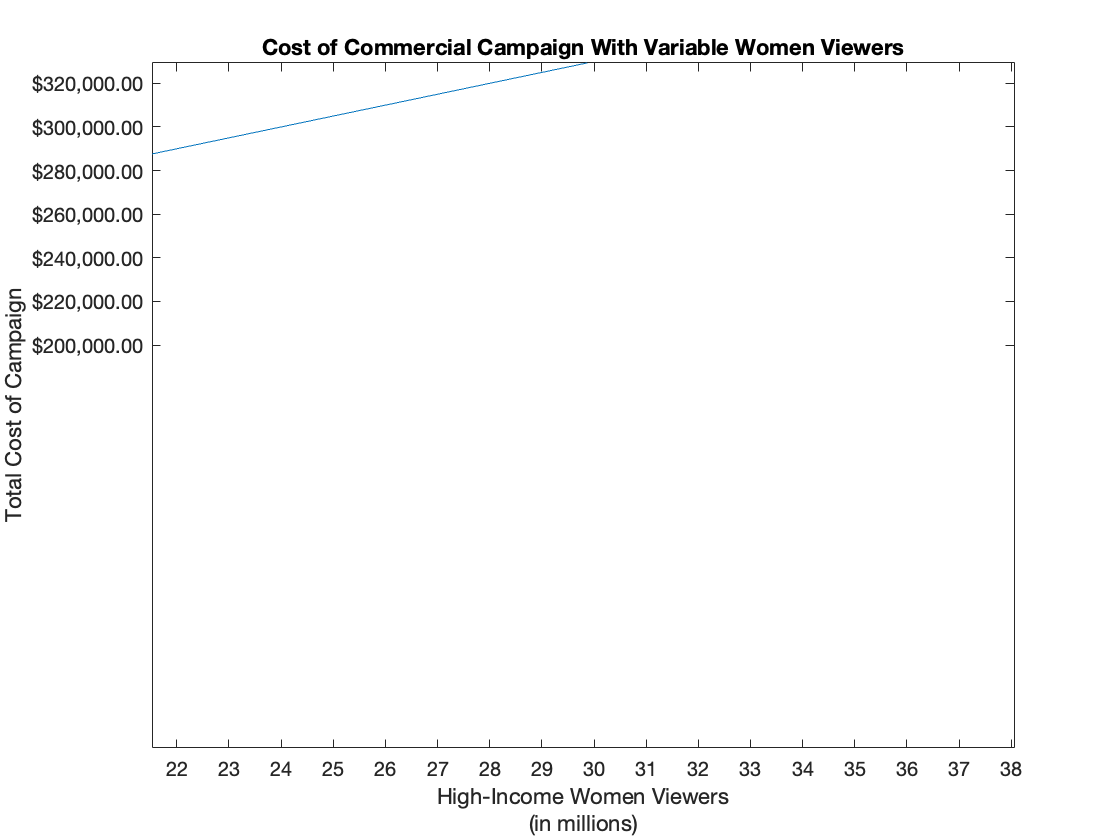

plot(W,z(3,:));
ylabel('Total Cost of Campaign')
xlabel({'High-Income Women Viewers', '(in millions)'})
title('Cost of Commercial Campaign With Variable Women Viewers')
xticks(20:40)
ytickformat('usd')
ylim([0 inf])
yticks([0 200000 220000 240000 260000 280000 300000 320000 340000 360000 380000])

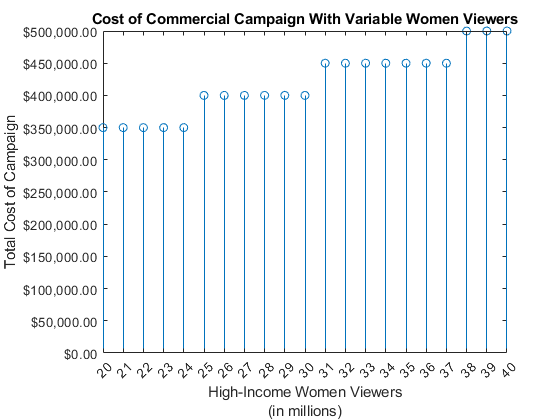

stem(W,z(5,:));
ylabel('Total Cost of Campaign')
xlabel({'High-Income Women Viewers', '(in millions)'})
title('Cost of Commercial Campaign With Variable Women Viewers')
xticks(20:40)
ytickformat('usd')